## 姿勢計算50本ノック

## 1-03 1-00で求めた主慣性軸方向を3次元空間に矢印でプロットせよ

clc
clear
close all

## 慣性テンソル

対称行列であることに注意

J = [10 2 -3
    2 14 1
    -3 1 16];

## 主慣性モーメント

[v, d] = eig(J);


慣性テンソルの対角化はテンソルの回転と等価なので固有ベクトル方向のプロットでok

v^(-1) * J * v % 一応確認

ans =    7.936527669377200   0.000000000000002   0.000000000000002
   0.000000000000003  14.811408421444380   0.000000000000000
  -0.000000000000002   0.000000000000000  17.252063909178421


d

d =    7.936527669377194                   0                   0
                   0  14.811408421444380                   0
                   0                   0  17.252063909178421


## plot

`quiver3`を使う

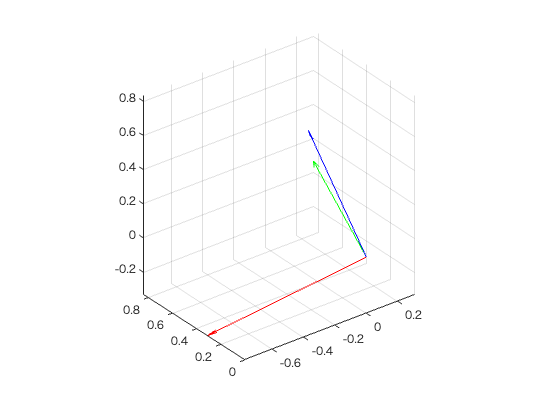

figure
quiver3(0, 0, 0, v(1,1), v(2,1), v(3,1), 'r') % quiver3便利
hold on % 重ねるのでhold on
quiver3(0, 0, 0, v(1,2), v(2,2), v(3,2), 'g')
quiver3(0, 0, 0, v(1,3), v(2,3), v(3,3), 'b')
axis equal % aspect比を1:1:1に